close all; clc; clearvars;

T = readtable("CaracteristicasDETECCION.csv");
T_error = readtable("T_buenacalidad_revisadas_ERRORES.csv");

#### Correlation

images_with_error = T_error.image(T_error.error_segmentacion == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error = T_error.image(T_error.error_disco == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error = T_error.image(T_error.error_copa == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error = T_error.image(T_error.error_disco2 == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

fotos_buenas = { 'image_0010.jpg', 'image_0016.jpg', 'image_0034.jpg', 'image_0035.jpg', 'image_0041.jpg', 'image_0044.jpg', 'image_0058.jpg', 'image_0064.jpg', 'image_0077.jpg', 'image_0079.jpg', 'image_0081.jpg', 'image_0083.jpg', 'image_0084.jpg', 'image_0085.jpg', 'image_0088.jpg', 'image_0089.jpg', 'image_0090.jpg', 'image_0093.jpg', 'image_0095.jpg', 'image_0105.jpg', 'image_0110.jpg', 'image_0124.jpg', 'image_0126.jpg','image_0128.jpg','image_0129.jpg','image_0136.jpg','image_0139.jpg','image_0144.jpg','image_0146.jpg','image_0148.jpg', 'image_0153.jpg', 'image_0154.jpg', 'image_0155.jpg', 'image_0164.jpg', 'image_0167.jpg', 'image_0169.jpg', 'image_0170.jpg', 'image_0175.jpg', 'image_0185.jpg', 'image_0189.jpg', 'image_0199.jpg', 'image_0201.jpg',  'image_0216.jpg', 'image_0224.jpg', 'image_0226.jpg', 'image_0227.jpg'};
T = T(ismember(T.imagen, fotos_buenas), :);

% fotos_buenas = { 'image_0010.jpg', 'image_0016.jpg','image_0027.jpg','image_0034.jpg', 'image_0035.jpg',  'image_0044.jpg','image_0048.jpg', 'image_0049.jpg', 'image_0052.jpg', 'image_0053.jpg', 'image_0055.jpg', 'image_0058.jpg', 'image_0064.jpg', 'image_0077.jpg', 'image_0079.jpg', 'image_0084.jpg', 'image_0090.jpg', 'image_0093.jpg', 'image_0095.jpg', 'image_0105.jpg', 'image_0110.jpg', 'image_0124.jpg', 'image_0126.jpg','image_0128.jpg','image_0146.jpg','image_0148.jpg'};
% T = T(ismember(T.imagen, fotos_buenas), :);
T

T = 46×34 table
    entropia    entropiaR    entropiaG    entropiaB     rango_dinamico    rango_dinamicoR    rango_dinamicoG    rango_dinamicoB    std_intensidad    var_intensidad    var_intensidadR    var_intensidadG    var_intensidadB     CDR       DDLS       dist1     dist2      dist3     dist4     radioC    radioD    centro1    centro2    NRR_area_ratio    media     media_r    media_g    media_b    nitidez_borde    nitidez_bordeR    nitidez_bordeG    nitide

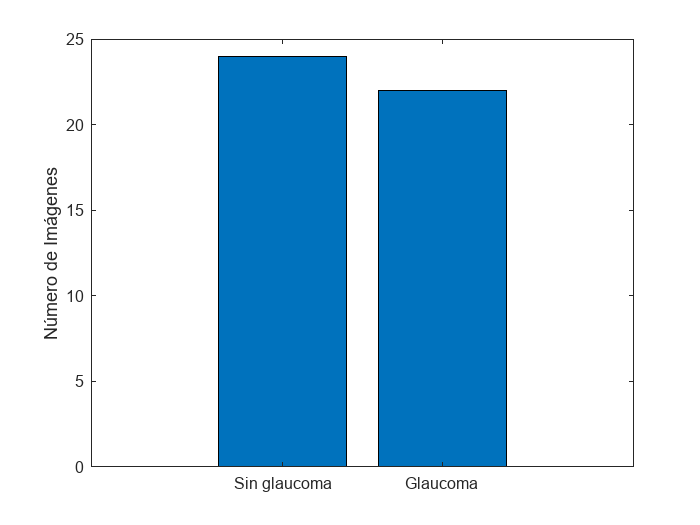


num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);

% Crear un vector con el número de imágenes para cada categoría
num_imagenes = [num_buenas, num_malas];

% Crear un gráfico de barras
figure;
bar(num_imagenes);
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});


T.imagen=[];
T.NRR_area_ratio=[];
% T.std_intensidad=[];
% T.dist1=[];
% T.dist2=[];
% T.dist3=[];
% T.dist4=[];
T.centro1=[];
T.centro2=[];
T.nitidez_borde=[];
T.nitidez_bordeG=[];
T.nitidez_bordeR=[];
T.nitidez_bordeB=[];
T.media = [];
T.media_r = [];
T.media_b = [];
T.media_g = [];
% T.radioC = [];
% T.radioD = [];
T.var_intensidadR=[];
T.var_intensidadG=[];
T.var_intensidadB=[];
T.entropiaR=[];
T.entropiaG=[];
T.entropiaB=[];
T.rango_dinamicoR=[];
T.rango_dinamicoG=[];
T.rango_dinamicoB=[];
% T.entropia=[];
T.var_intensidad=[];
T.rango_dinamico=[];
T.DDLS=[];

variables=T.Properties.VariableNames

variables = 1×10 cell array
    {'entropia'}    {'std_intensidad'}    {'CDR'}    {'dist1'}    {'dist2'}    {'dist3'}    {'dist4'}    {'radioC'}    {'radioD'}    {'glaucoma'}


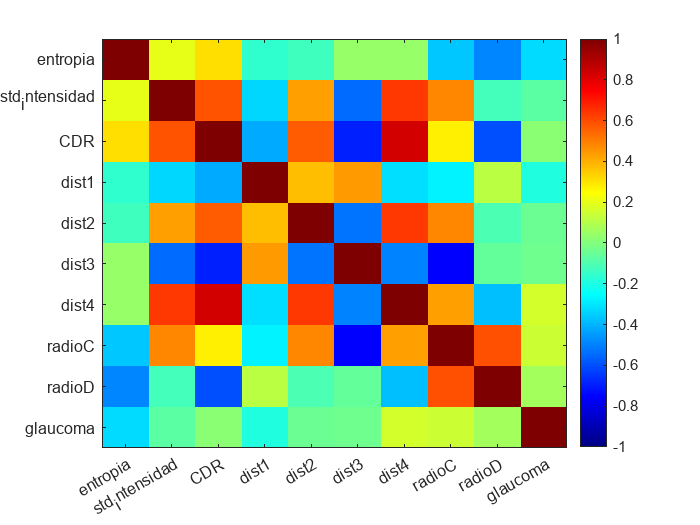


X = T{:, :};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:));
yticks(1:30);
yticklabels(variables(:));
colormap(jet); colorbar;

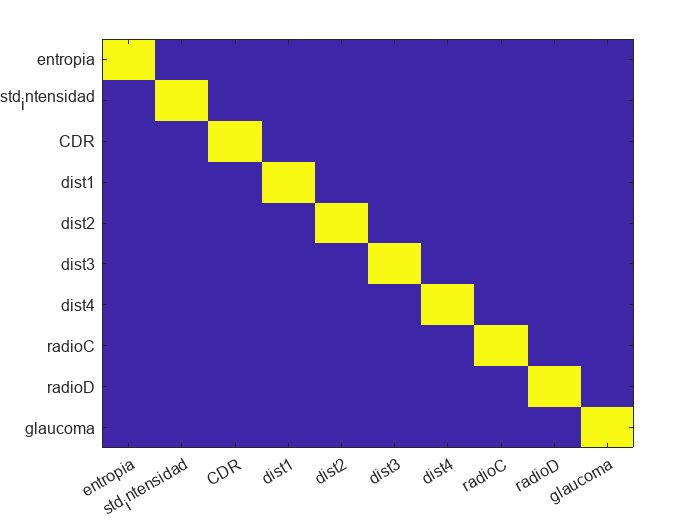


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:30);
xticklabels(variables(:));
yticks(1:30);
yticklabels(variables(:));

#### Preprocessing

[n, ~]=size(T);

T.glaucoma = cellstr(num2str(T.glaucoma)); %convertir quality en variable categorica
for i = 1:n
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No Glaucoma';
    end
end

### 2. Data split

rng(6); 
p = 0.2;
cv_out = cvpartition(T.glaucoma, 'HoldOut', p, 'Stratify', true); 
% 20% -> pruebas
% 80% -> entrenar el modelo. 
% 'Stratify', true asegura que la distribución de clases se mantenga tanto en los conjuntos de entrenamiento como en los de prueba

T_train = T(cv_out.training, :); 
T_test  = T(cv_out.test, :);

k = 10; % técnica de validación cruzada de 10 pliegues
cv_in = cvpartition(T_train.glaucoma, 'KFold', k, 'Stratify', true);

### **3. Model training**

results = table;

#### **K-nearest neighbors (KNN)**

mdl_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in); % number of neighbors: 3
mdl_loss = kfoldLoss(mdl_knn); % mean error value

Y_pred = kfoldPredict(mdl_knn);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("knn", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Classification Trees**

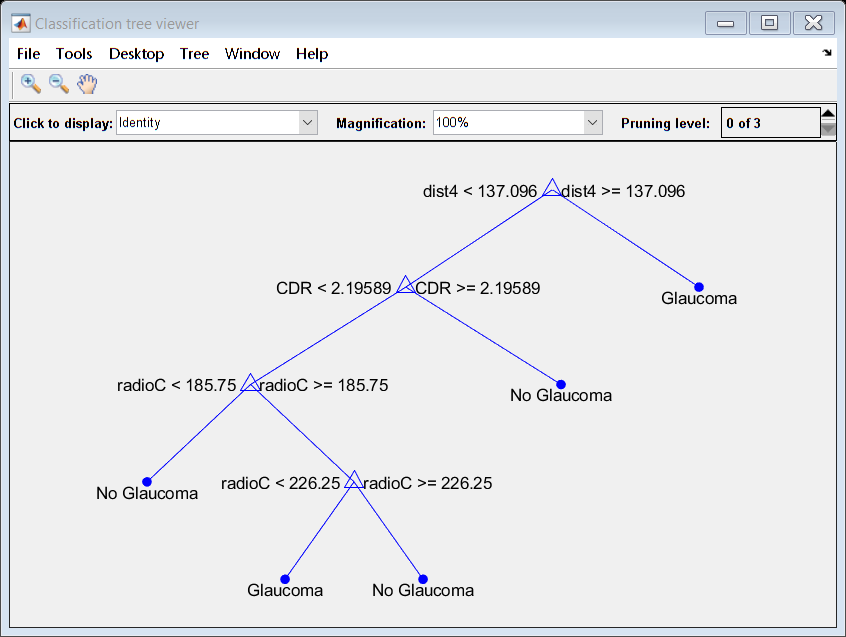

mdl_tree = fitctree(T_train, 'glaucoma', 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

accuracy = sum(strcmp(T_train.glaucoma, Y_pred)) / height(T_train);
results = [results; table("tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

first_fold_tree = mdl_tree.Trained{1};
view(first_fold_tree, 'Mode', 'graph');

#### Naive Bayes

mdl_NB = fitcnb(T_train, 'glaucoma','CVPartition', cv_in);
% mdl_loss = kfoldLoss(mdl_NB);

Y_pred = kfoldPredict(mdl_NB);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### Discriminant Analysis

- **LDA**: asume que las matrices de covarianza de cada clase son iguales.

mdl_lda = fitcdiscr(T_train, 'glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_lda);
Y_pred = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);

results = [results; table("LDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

- **QDA:** asume que las matrices de covarianza de cada clase son diferentes.

% mdl_qda = fitcdiscr(T_train, 'glaucoma','DiscrimType','quadratic','CVPartition',cv_in);
% mdl_loss = kfoldLoss(mdl_qda);
% 
% Y_pred = kfoldPredict(mdl_qda);
% 
% accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
% results = [results; table("QDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Support Vector Machines (SVM)**

mdl_svm = fitcecoc(T_train, 'glaucoma','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);

Y_pred = kfoldPredict(mdl_svm);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

### 4. Model comparison

results

results = 5×3 table
        model         loss      accuracy
    _____________    _______    ________

    "knn"            0.51351    0.48649 
    "tree"           0.45946    0.54054 
    "naive_bayes"    0.45946    0.40541 
    "LDA"            0.48649    0.51351 
    "SVM"            0.35135    0.64865 


[~, best_model] = max(results.accuracy);
results(best_model, :) %balance accuracy

ans = 1×3 table
    model     loss      accuracy
    _____    _______    ________

    "SVM"    0.35135    0.64865 


### 5. Final model testing

#### **Support Vector Machines (SVM)**

mdl_final_SVM = fitcecoc(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_SVM, T_test);

loss_final2 = loss(mdl_final_SVM, T_test)

loss_final2 = 0.3270

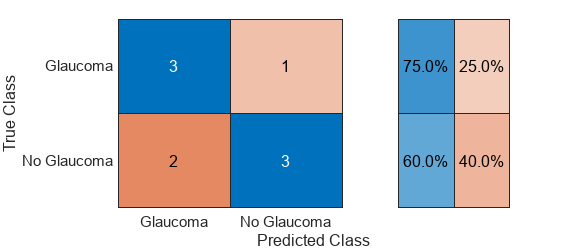

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')


mdl_final_LDA = fitcdiscr(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_LDA, T_test);

loss_final2 = loss(mdl_final_LDA, T_test)

loss_final2 = 0.3270

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')


mdl_final_tree = fitctree(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_tree, T_test);

loss_final2 = loss(mdl_final_tree, T_test)

loss_final2 = 0

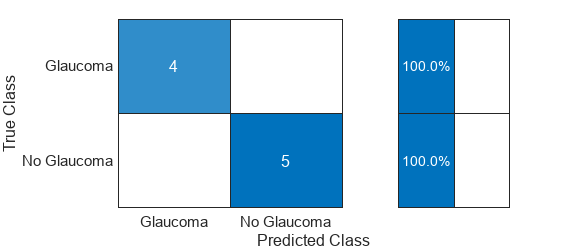

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')

T_metadata = readtable('metadataCALIDADCORRECTA.csv');
I = imread(T_metadata.image{1});

filtro_laplace=[1, 1, 1; 1, -8, 1; 1, 1, 1];
I_gray = rgb2gray(I);

I_borde = imbinarize(I_gray, 0.15);

% quitar los puntos blancos que aparecen fuera del ciruclo
se = strel('disk', 15);
I_borde = imerode(I_borde, se);

I = im2double(I);
I(:, :, 1) = I(:, :, 1) .* I_borde;
I(:, :, 2) = I(:, :, 2) .* I_borde;
I(:, :, 3) = I(:, :, 3) .* I_borde;

I = im2uint8(I);

% OSCURECER BORDES 
se = strel('disk', 100); 
bordes = imerode(I_borde, se); 
I_gray_oscura = I_gray * 0;
I_gray_oscura(bordes) = I_gray(bordes);

I_gray_oscura = adapthisteq(I_gray_oscura);

[max_fila, max_columna] = find(I_gray_oscura == max(I_gray_oscura(:)));
centroide_x = mean(max_fila);
centroide_y = mean(max_columna);

s = size(I_gray_oscura);
tamano_roi = min(s)/2;

inicio_x = max(1, round(centroide_x - tamano_roi/2));
fin_x = min(size(I_gray, 1), round(centroide_x + tamano_roi/2));
inicio_y = max(1, round(centroide_y - tamano_roi/2));
fin_y = min(size(I_gray, 2), round(centroide_y + tamano_roi/2));

roi = I(inicio_x:fin_x, inicio_y:fin_y, :);

red_channel = roi(:, :, 1);
green_channel = roi(:, :, 2);
blue_channel = roi(:, :, 3);
I_gray = rgb2gray(roi);

se = strel('disk', 30); 

canal_verde_sin_vasos = imclose(green_channel, se);
canal_rojo_sin_vasos = imclose(red_channel, se); %el canal rojo no tiene vasos
canal_azul_sin_vasos = imclose(blue_channel, se);
gray_sin_vasos = imclose (I_gray, se);

gray_sin_vasos1 = adapthisteq(gray_sin_vasos);
canal_azul_sin_vasos1 = adapthisteq(canal_azul_sin_vasos);
canal_verde_sin_vasos1 = adapthisteq(canal_verde_sin_vasos);
canal_rojo_sin_vasos1 = adapthisteq(canal_rojo_sin_vasos);

gray_sin_vasos2 = histeq(gray_sin_vasos);
canal_azul_sin_vasos2 = histeq(canal_azul_sin_vasos);
canal_verde_sin_vasos2 = histeq(canal_verde_sin_vasos);
canal_rojo_sin_vasos2 = histeq(canal_rojo_sin_vasos);

e_gris = entropy(I_gray);
e_rojo = entropy(red_channel); % si es mas de 6 bien
e_verde = entropy(green_channel);
e_azul = entropy(blue_channel); % si es menos de 4 -> no usar %a partir de 6 no usar

if e_gris > 5 && e_gris < 6 
    cup_threshold = 0.85 * max(gray_sin_vasos1(:)); % Umbral para la copa (brillo)
    disc_threshold = 0.95 * max(gray_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    cup_binary = gray_sin_vasos1 > cup_threshold; % Segmentación de la copa
    disc_binary = gray_sin_vasos2 > disc_threshold; % Segmentación del disco completo
else 
    cup_binary = ones(size(gray_sin_vasos));
    disc_binary = ones(size(gray_sin_vasos));
end

if e_rojo > 6.5
    cup_thresholdR = 0 * max(canal_rojo_sin_vasos1(:)); % Umbral para la copa (brillo)
    disc_thresholdR = 0.95 * max(canal_rojo_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    cup_binaryR = canal_rojo_sin_vasos1 > cup_thresholdR; % Segmentación de la copa
    disc_binaryR = canal_rojo_sin_vasos2 > disc_thresholdR; % Segmentación del disco completo
else 
    cup_binaryR = ones(size(gray_sin_vasos));
    disc_binaryR = ones(size(gray_sin_vasos));
end

if e_verde > 4.5
    cup_thresholdG = 0.85 * max(canal_verde_sin_vasos1(:)); % Umbral para la copa (brillo)
    disc_thresholdG = 0.9 * max(canal_verde_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)
    
    cup_binaryG = canal_verde_sin_vasos1 > cup_thresholdG; % Segmentación de la copa
    disc_binaryG = canal_verde_sin_vasos2 > disc_thresholdG; % Segmentación del disco completo
else 
    cup_binaryG = ones(size(gray_sin_vasos));
    disc_binaryG = ones(size(gray_sin_vasos));
end
 
if e_azul > 5 && e_azul < 6
    cup_thresholdB = 0.8 * max(canal_azul_sin_vasos1(:)); % Umbral para la copa (brillo)
    disc_thresholdB = 0.9 * max(canal_azul_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)
    
    cup_binaryB = canal_azul_sin_vasos1 > cup_thresholdB; % Segmentación de la copa
    disc_binaryB = canal_azul_sin_vasos2 > disc_thresholdB; % Segmentación del disco completo
else 
    cup_binaryB = ones(size(gray_sin_vasos));
    disc_binaryB = ones(size(gray_sin_vasos));
end

% Operación lógica de intersección para la segmentación de la copa
cup_binary_comun = cup_binary & cup_binaryR & cup_binaryG & cup_binaryB;

se = strel('disk', 10);
disc_binaryR = imdilate(disc_binaryR, se);
% Operación lógica de intersección para la segmentación del disco
disc_binary_comun = disc_binary & disc_binaryR & disc_binaryG  & disc_binaryB;

se = strel('disk', 15);
disco = imerode(disc_binary_comun, se);
disco = bwareafilt(disco, 1);
disco = imdilate(disco, se);
copa = bwareafilt(cup_binary_comun, 1);
copa = imdilate(copa, se);

[filaD, columnaD] = find(disco == max(disco(:)));
% Calcula el centroide
centroide_x = mean(columnaD);
centroide_y = mean(filaD);
centro_disco = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(filaD) - min(filaD);
alto_maximo = max(columnaD) - min(columnaD);
radio_disco = max(ancho_maximo, alto_maximo) / 2;

[filaC, columnaC] = find(copa == max(copa(:)));
% Calcula el centroide
centroide_x = mean(columnaC);
centroide_y = mean(filaC);
centro_copa = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(filaC) - min(filaC);
alto_maximo = max(columnaC) - min(columnaC);
radio_copa = max(ancho_maximo, alto_maximo) / 2;

red_channel = roi(:, :, 1);
green_channel = roi(:, :, 2);
blue_channel = roi(:, :, 3);
red_channel = double(red_channel);
green_channel = double(green_channel);
blue_channel = double(blue_channel);

entropia = entropy(roi);

I = double(rgb2gray(roi)); % damos por hecho que la imagen es de color (igual hacer un for para diferenciar)
media =mean(roi(:));
media_g =mean(green_channel(:));
media_b =mean(blue_channel(:));
media_r =mean(red_channel(:));

rango_dinamico=max(I(:))-min(I(:));
rango_dinamicoR=max(red_channel(:))-min(red_channel(:));
rango_dinamicoG=max(green_channel(:))-min(green_channel(:));
rango_dinamicoB=max(blue_channel(:))-min(blue_channel(:));
std_intensidad = std2(I(:)); % desviación estandar
var_intensidad =var(I(:)); % varianza
var_intensidadR =var(red_channel(:)); % varianza
var_intensidadG =var(green_channel(:)); % varianza
var_intensidadB =var(blue_channel(:)); % varianza
I2=imfilter(roi, filtro_laplace);
nitidez_borde = sum(abs(I2(:)));
I3=imfilter(red_channel, filtro_laplace);
nitidez_bordeR = sum(abs(I3(:)));
I4=imfilter(green_channel, filtro_laplace);
nitidez_bordeG = sum(abs(I4(:)));
I5=imfilter(blue_channel, filtro_laplace);
nitidez_bordeB = sum(abs(I5(:)));

CDR = radio_disco/radio_copa;

RIM = radio_disco-radio_copa;
DDLS = RIM/radio_disco;

dist1 = (centro_disco(1)-radio_disco)-(centro_copa(1)-radio_copa);
dist2 = (centro_disco(1)+radio_disco)-(centro_copa(1)+radio_copa);
dist3 = (centro_disco(2)-radio_disco)-(centro_copa(2)-radio_copa);
dist4 = (centro_disco(2)+radio_disco)-(centro_copa(2)+radio_copa);

radioC = radio_copa;
radioD = radio_disco;

centro1 = centro_disco(1) - centro_copa(1);
centro2 = centro_disco(2) - centro_copa(2);

% Create a meshgrid for the coordinates
[x, y] = meshgrid(1:size(disco, 2), 1:size(disco, 1));

% Calculate distances from the center
distX = x - centro_disco(1);
distY = y - centro_disco(2);

% Determine the quadrants
inferior = distY > 0; % Inferior quadrants (y > center_y)
superior = distY <= 0; % Superior quadrants (y <= center_y)
nasal = distX <= 0;    % Nasal quadrants (x <= center_x)
temporal = distX > 0;  % Temporal quadrants (x > center_x)

% Calculate areas in each quadrant for the disc
area_inferior_disc = sum(disco(inferior), 'all');
area_superior_disc = sum(disco(superior), 'all');
area_nasal_disc = sum(disco(nasal), 'all');
area_temporal_disc = sum(disco(temporal), 'all');

% Calculate areas in each quadrant for the cup
area_inferior_cup = sum(copa(inferior), 'all');
area_superior_cup = sum(copa(superior), 'all');
area_nasal_cup = sum(copa(nasal), 'all');
area_temporal_cup = sum(copa(temporal), 'all');

% Total areas in each region (disc - cup)
total_inferior = area_inferior_disc - area_inferior_cup;
total_superior = area_superior_disc - area_superior_cup;
total_nasal = area_nasal_disc - area_nasal_cup;
total_temporal = area_temporal_disc - area_temporal_cup;

% Calculate the NRR area ratio
NRR_area_ratio = (total_inferior + total_superior) / (total_nasal + total_temporal);

T_caracteristicas_DETECCION = table(entropia, rango_dinamico, rango_dinamicoR, rango_dinamicoG,rango_dinamicoB, std_intensidad, var_intensidad, var_intensidadR, var_intensidadG, var_intensidadB, CDR, DDLS, dist1, dist2, dist3, dist4, radioD, radioC, centro1, centro2, NRR_area_ratio, media, media_r, media_g, media_b, nitidez_borde, nitidez_bordeR, nitidez_bordeG, nitidez_bordeB, 'VariableNames', {'entropia', 'rango_dinamico', 'rango_dinamicoR', 'rango_dinamicoG', 'rango_dinamicoB', 'std_intensidad', 'var_intensidad', 'var_intensidadR', 'var_intensidadG', 'var_intensidadB', 'CDR', 'DDLS', 'dist1', 'dist2', 'dist3', 'dist4', 'radioC', 'radioD', 'centro1', 'centro2','NRR_area_ratio', 'media', 'media_r', 'media_g', 'media_b', 'nitidez_borde', 'nitidez_bordeR', 'nitidez_bordeG', 'nitidez_bordeB'}); 

prediccion4 = predict(mdl_final_SVM, T_caracteristicas_DETECCION);

Unrecognized function
or variable
'mdl_final_SVM'.